# HW4

Yuyu Fan

%Problem 1
load hw4_1_data
%perform PCA
C = cov(X); 
[U, S, V] = svd(C);
U1 = U(:, 1); 
U2 = U(:, 2);
U3 = U(:, 3);

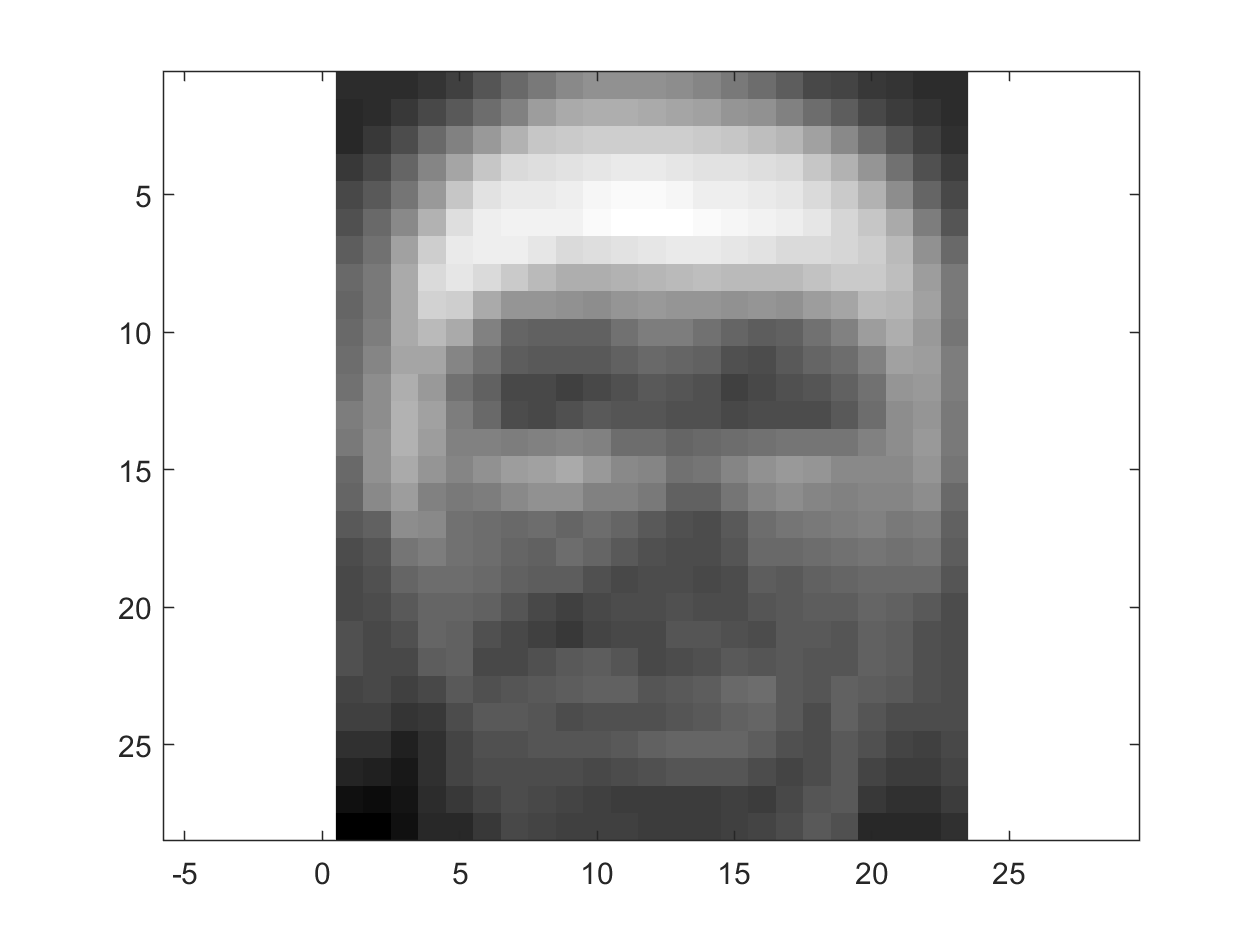

 %Show images of the first three principal directions of the data
I1 = reshape(U1,28,23);
    figure(1)
    imagesc(I1);
     colormap(gray)
     axis equal;

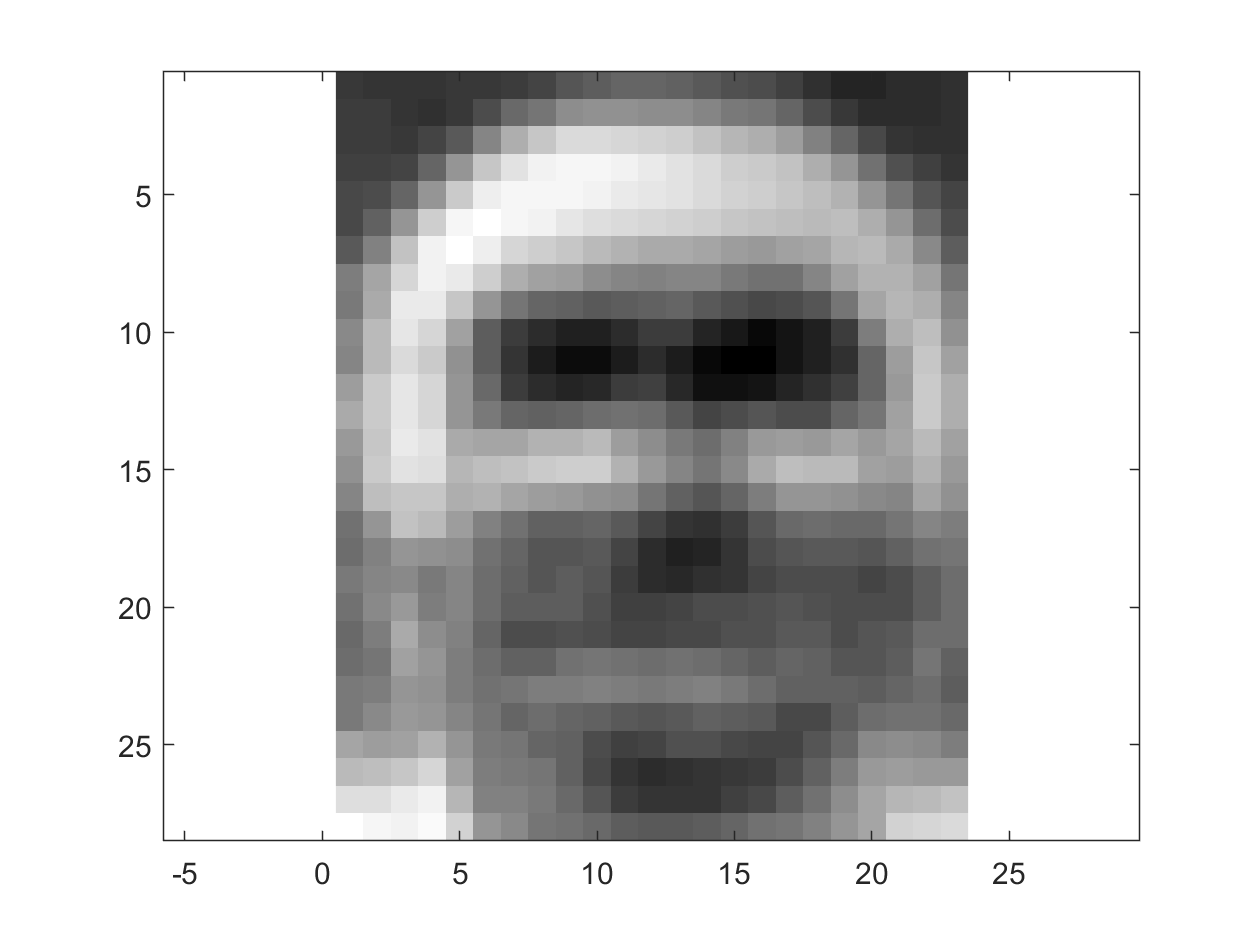

I2 = reshape(U2,28,23);
    figure(2)
    imagesc(I2);
     colormap(gray)
     axis equal;

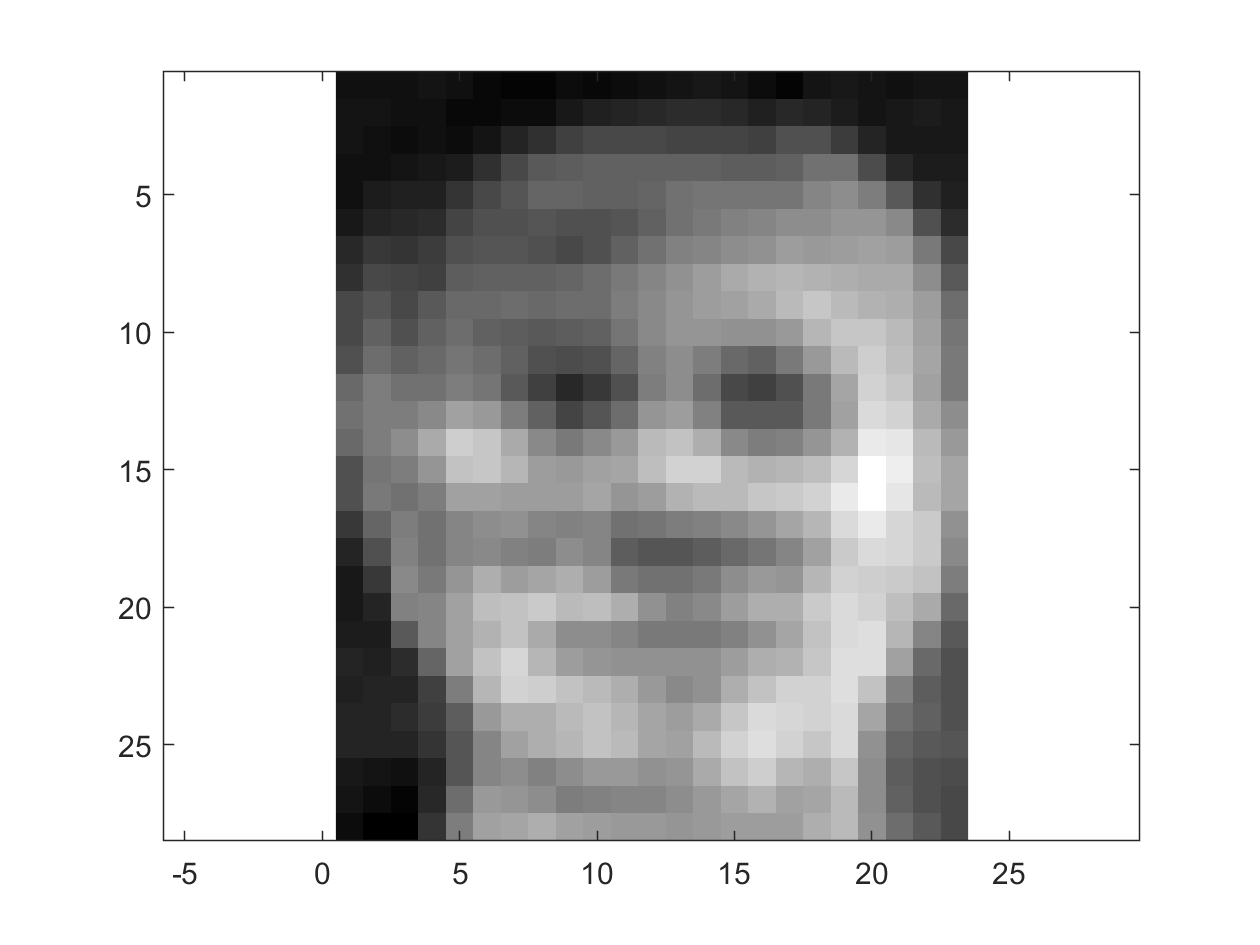

I3 = reshape(U3,28,23);
    figure(3)
    imagesc(I3);
     colormap(gray)
     axis equal;

% projection of the first image into first d components
type proj.m


function result = proj(X,U,d) 
  temp = zeros(size(U(:,1))); 
for i = 1 : d 
    temp = temp + X * U(:, i) * U(:, i);
end
result = temp;


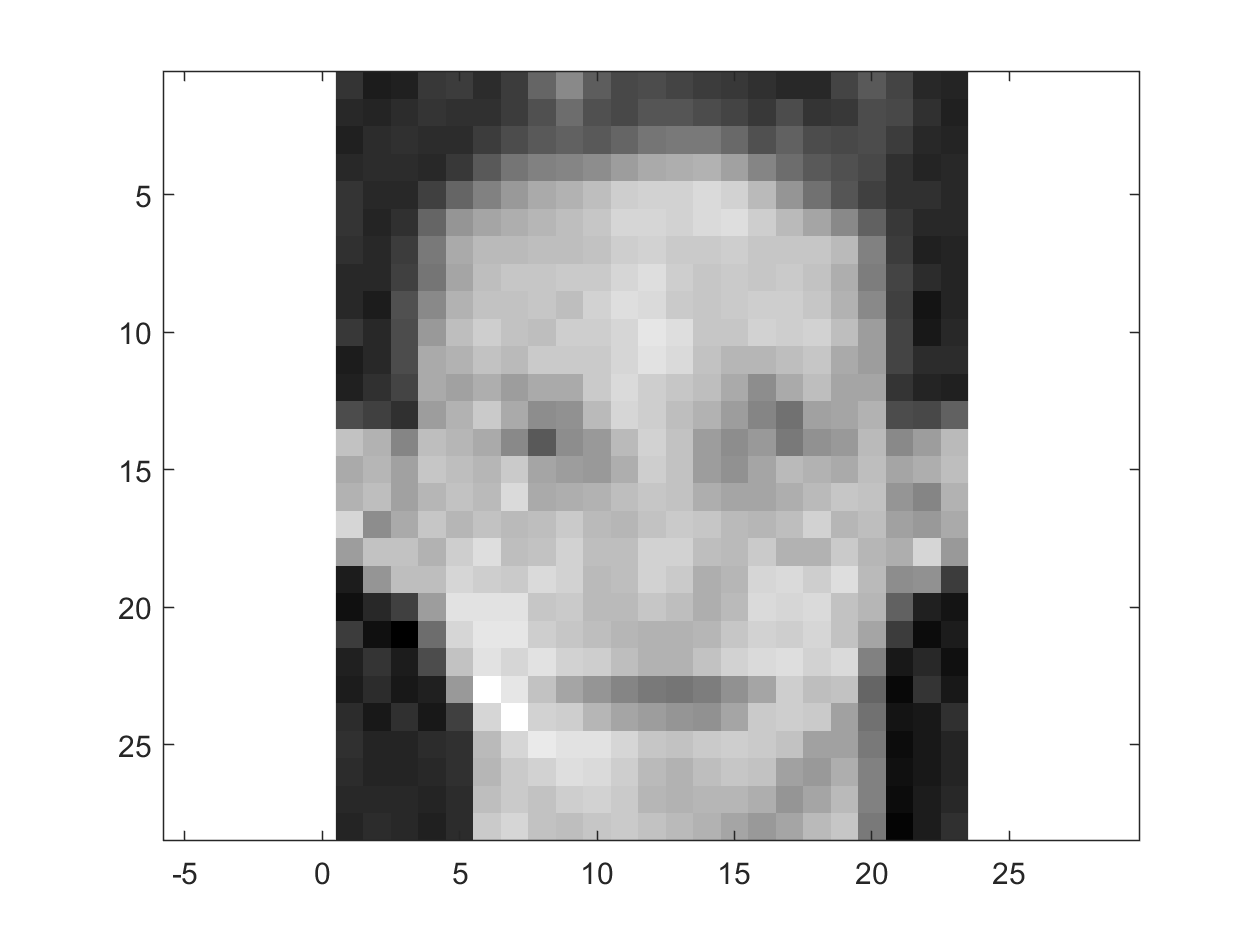

proj1=proj(X(1,:),U,50);
proj2=proj(X(1,:),U,100);
I5 = reshape(X(1,:),28,23);
    figure(5)
    imagesc(I5);
     colormap(gray)
     axis equal;

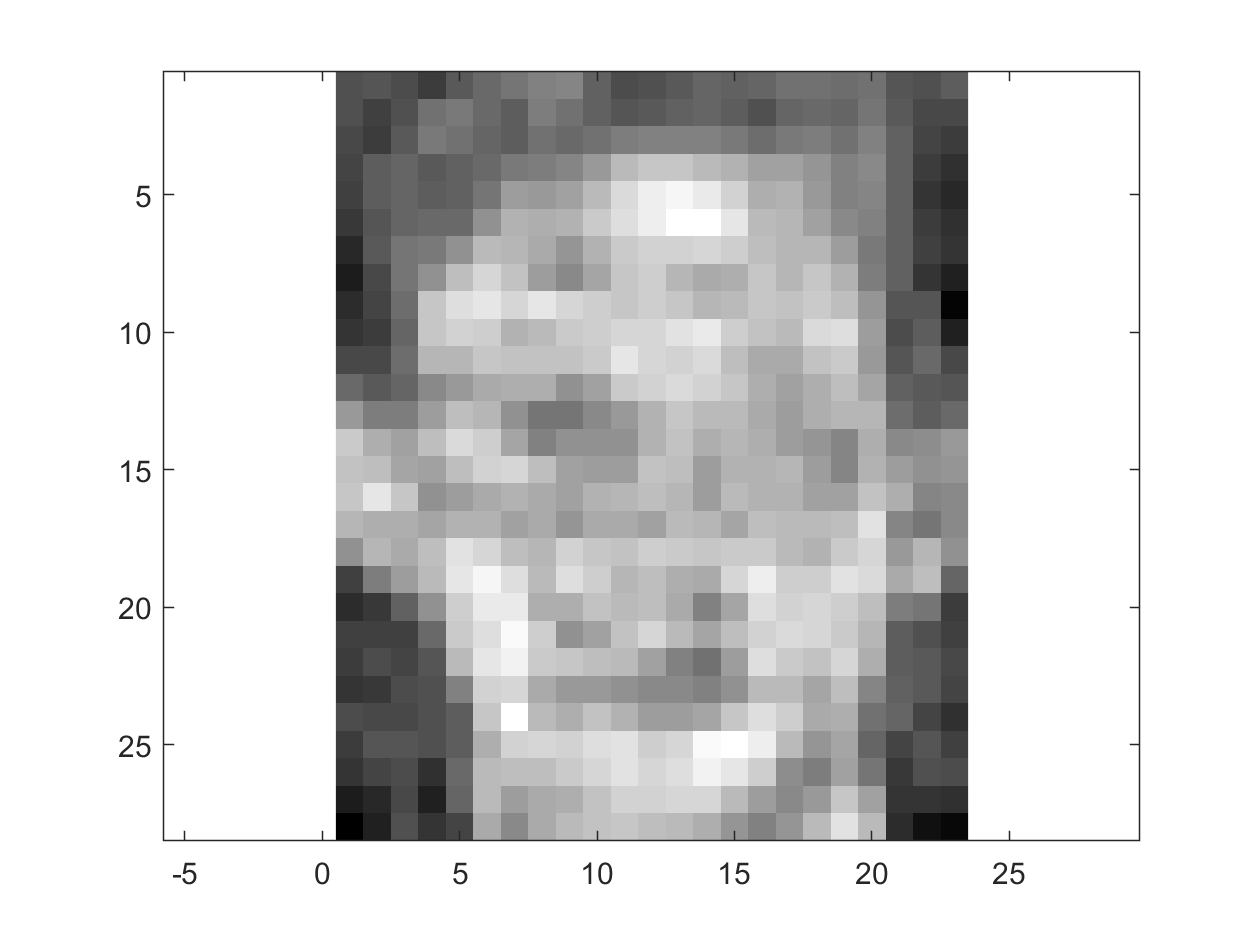

I6 = reshape(proj1,28,23);
    figure(6)
    imagesc(I6);
     colormap(gray)
     axis equal;

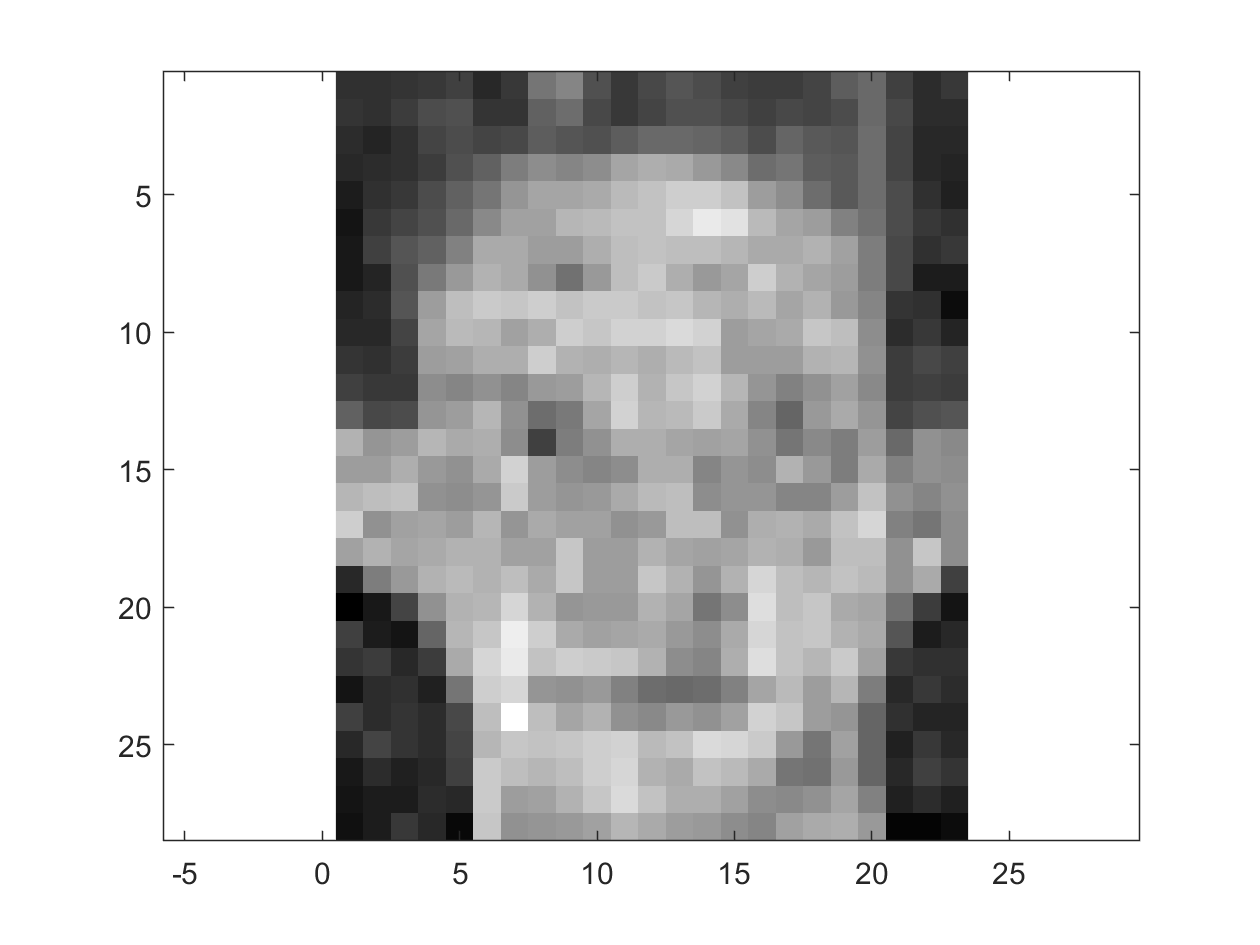

I7 = reshape(proj2,28,23);
    figure(7)
    imagesc(I7);
     colormap(gray)
     axis equal;

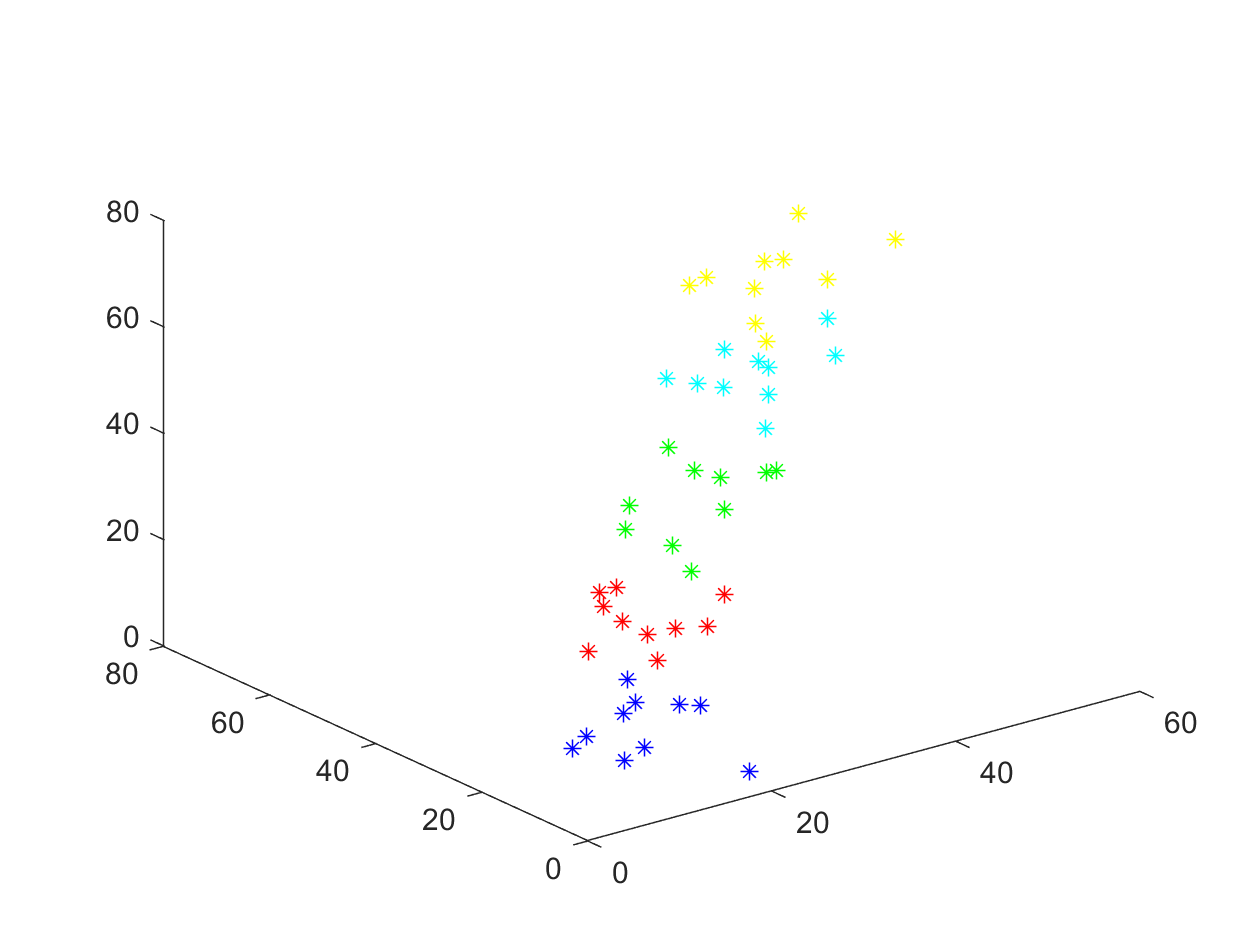

% Problem 2
%plot original data 

load hw4_2_data;
[n, m, k] = size(X);
% plot X
figure(1);
color = 'brgcy';
for j = 1:m
    for i = 1:k
        plot3(X(1,j,i), X(2,j,i),X(3,j,i), [color(j) '*']);
        hold on;
    end
end 

% compute mean in each class
for i = 1:n
    for j = 1:m
        mu(i,j) = mean(X(i,j,:));
    end
end
% compute total mean
MU = mean(mu, 2);

% compute between-class scatter matrix
S_B = zeros(n, n);
for j = 1:m
    S_B = S_B + (mu(:,j) - MU)*(mu(:,j) - MU)';
end
% compute within-class scatter matrix
S_W = zeros(n, n);
for j = 1:m
    for i = 1:k
        S_W = S_W + (X(:,j,i) - mu(:,j))*(X(:,j,i) - mu(:,j))';
    end
end


% compute U
[U, D] = eig(S_B, S_W);
U = U(:,n);% take the last component (w.r.t. largest generalized eigenvalue)
U

U =     0.0144
    0.0195
    0.0169


% projection to Z
for j = 1:m
    for i = 1:k
        Z(i,j) = U'*X(:,j,i);
    end
end
Z

Z =     0.5839    0.9808    1.5739    2.1483    2.7427
    0.4654    0.8587    1.8024    2.3971    2.8499
    0.5085    1.0998    1.5724    2.0108    2.7821
    0.8187    1.0414    1.4903    2.3203    2.6053
    0.3889    1.2592    1.8462    2.2554    3.0521
    0.6170    1.1758    1.3420    2.4029    2.8404
    0.5061    1.2395    1.8222    2.4276    2.7821
    0.5717    0.9166    1.8209    2.3067    2.7780
    0.6652    0.9945    1.8927    2.5497    2.5520
    0.3947    1.0493    1.6298    2.3357    2.8922


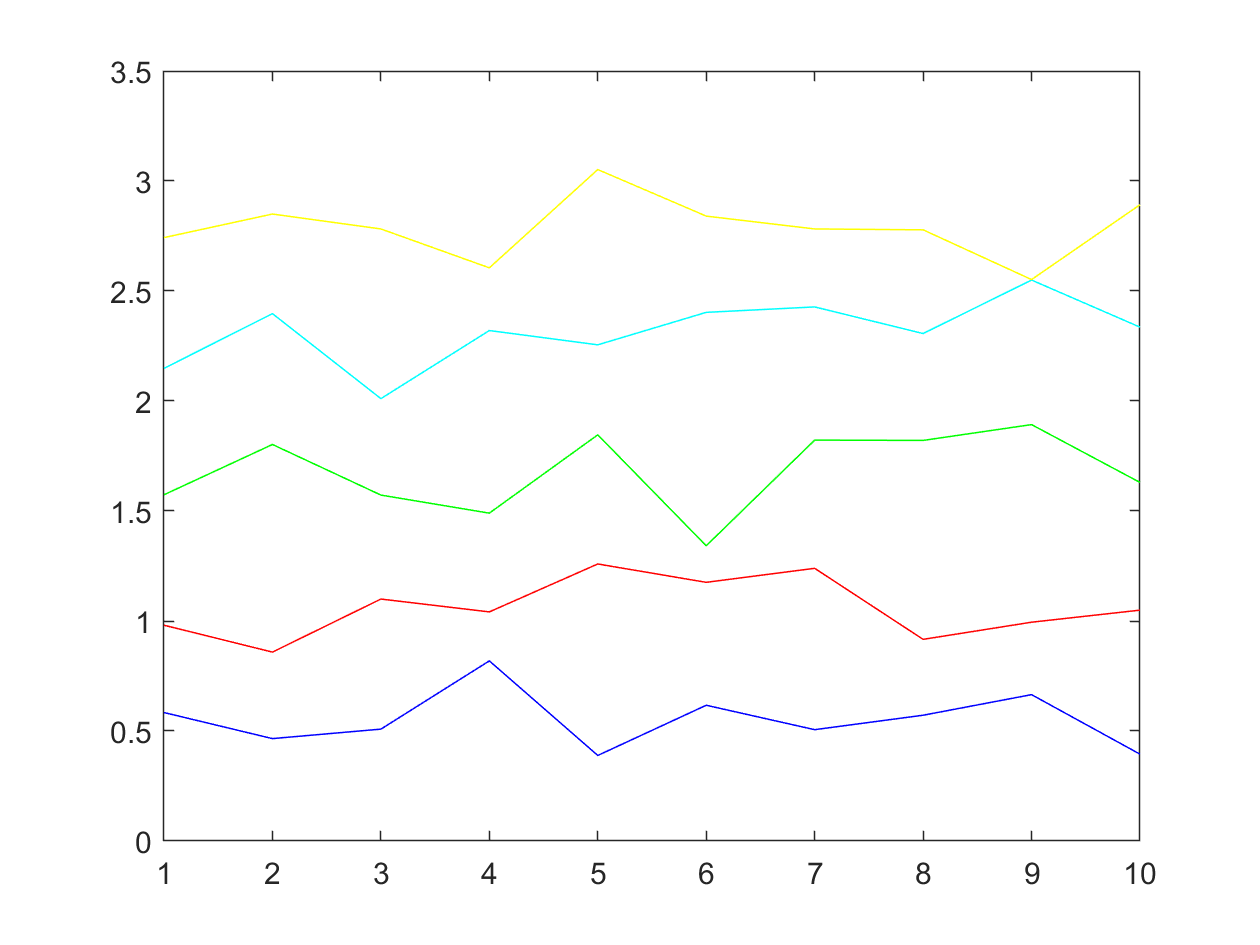

% plot Z
figure(2);


color = 'brgcy';
for j = 1:m
    plot(Z(:,j), [color(j)]);
    hold on;
end